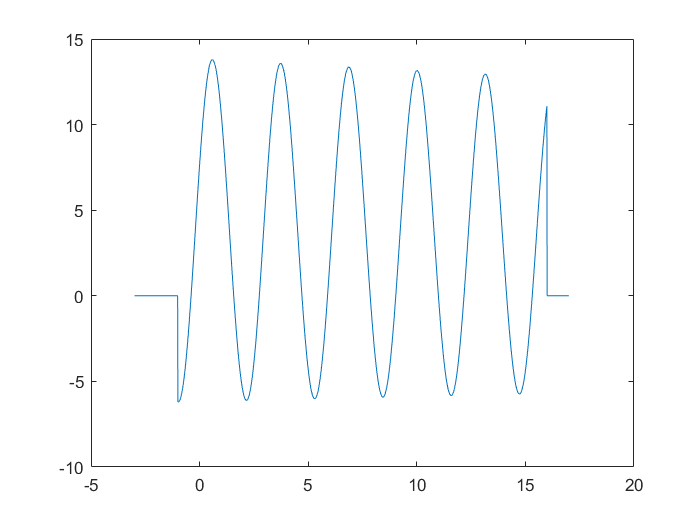

A1 = -19;
A2 = 199;
B = 0.001;
C1 = -2;
C2 = 214;
D = 512;
E1 = -10;
E2 = 9;
F1 = -3;
F2 = -4;
F3 = -2;
F4 = -1;
G1 = -3;
G2 = 17;
funH = 1;
% H = (20*exp(-t/200).*cos(t)).*sin(t+pi/8);
J1 = -1;
J2 = 16;
L = 6;
M = 5;
N = 40;
sucesion = 2;
% S(n) = 5*S(n-2) - 3;
P = 26;
F = 2;
% Filtro: filtro pasa altos
K = 10;
senalY = 4;
% Y = |sin(x/3)|;
Q = 69;
R = 3246;
% Senal_audio = 0.7*sin(2*pi*50*n) + sin(2*pi*120*n) + 2*randn(size(n));
T = 4;
U = 7;
V = 3;

Vector1=A1:B:A2;
Vector2=linspace(C1,C2,D);
Tiempo1=E1:E2;
Senal1=(1*dtimp(Tiempo1-F1))+(3*dtimp(Tiempo1-F2))-(2*dtimp(Tiempo1-F3))+(2*dtimp(Tiempo1-F4));
Tiempo2=G1:0.01:G2;
H=(20*exp(-Tiempo2/200).*cos(Tiempo2)).*sin(Tiempo2+pi/8);
Senal2=(ctstep(Tiempo2-J1)-ctstep(Tiempo2-J2)).*H;
figure
plot(Tiempo2,Senal2)

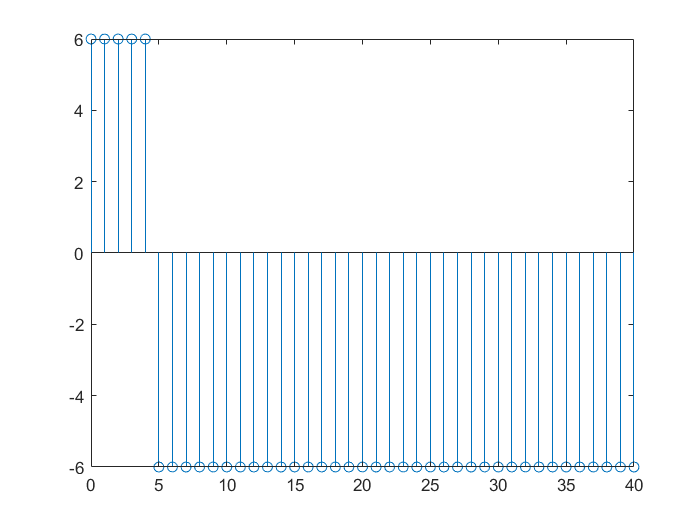

Minimo=min(Senal2);
Maximo=max(Senal2);

%Convolucion
time=0:N;
h1=(ctstep(time)*L)-(2*L*ctstep(time-M));
h2=(cos((pi/4)*time)).*ctstep(time);

figure
stem(time,h1)

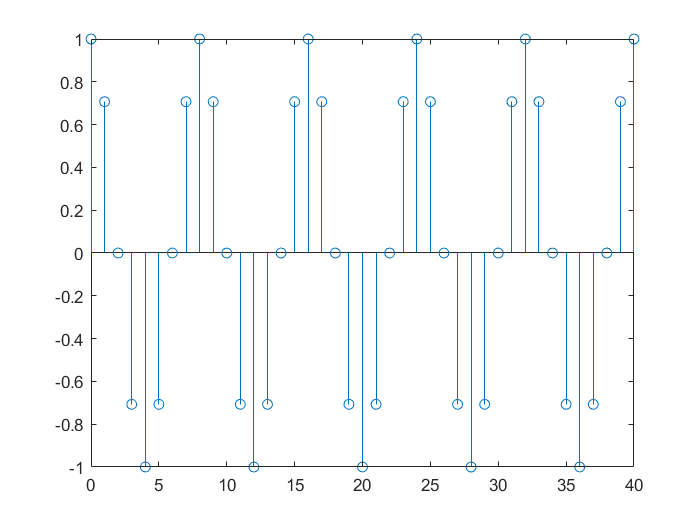

figure
stem(time,h2)

FuncionH=conv(h1,h2);
xconv=ctstep(time);
RespuestaY=conv(FuncionH,xconv);
%Funciones recurrentes
TerminoN=CalculoSucesion(P);
%Fourier
f0=Q;
T0=3*pi;
dt=1/(100*f0);
timeFourier=0:dt:10*T0;
Y = abs(sin(timeFourier/3));
index=1;
for k=-K:K
% Notice that this expression is also valid for k=0
    C_k(index)=dt*sum(Y.*exp(-1i*k*2*pi*timeFourier/T0))/(10*T0);
% Or equivalently: c(index)=mean(x.*exp(-1i*k*2*pi*t/T0));
    index=index+1;
end
fs=50000;
timeAudio=0:0.01:500;
Senal_audio = 0.7*sin(2*pi*50*timeAudio) + sin(2*pi*120*timeAudio) + 2*randn(size(timeAudio));
omega=linspace(-fs/2,fs/2,length(Senal_audio));
FFT_audio=fftshift(fft(Senal_audio));
magnitude_audio=abs(FFT_audio);
phase_audio=angle(FFT_audio);

omega_low=1000;
omega_high=R;

FiltroIdeal=ones(1,length(omega))-(ctstep(omega+omega_high)-ctstep(omega-omega_high));

Magnitud=magnitude_audio.*FiltroIdeal;

FFT_audio_high_filter=Magnitud.*exp(1i*phase_audio);

SenalAudioF=real(ifft(ifftshift(FFT_audio_high_filter)));

function dti=dtimp(n)
    dti=(n==0);
end
function cts = ctstep(t)
    cts=(t>=0).*1;
end
function s=CalculoSucesion(x)
    
    snm1=1;
    snm2=1;
    for i=1:x
        s(i)=5*snm2-3;        
        snm2=snm1;
        snm1=s(i);
    end
end
function dts= dtstep(n)
    dts = 1 * (floor(n) == n) .* (n >= 0);
end